# Ejercicio 2.5

 **a) **

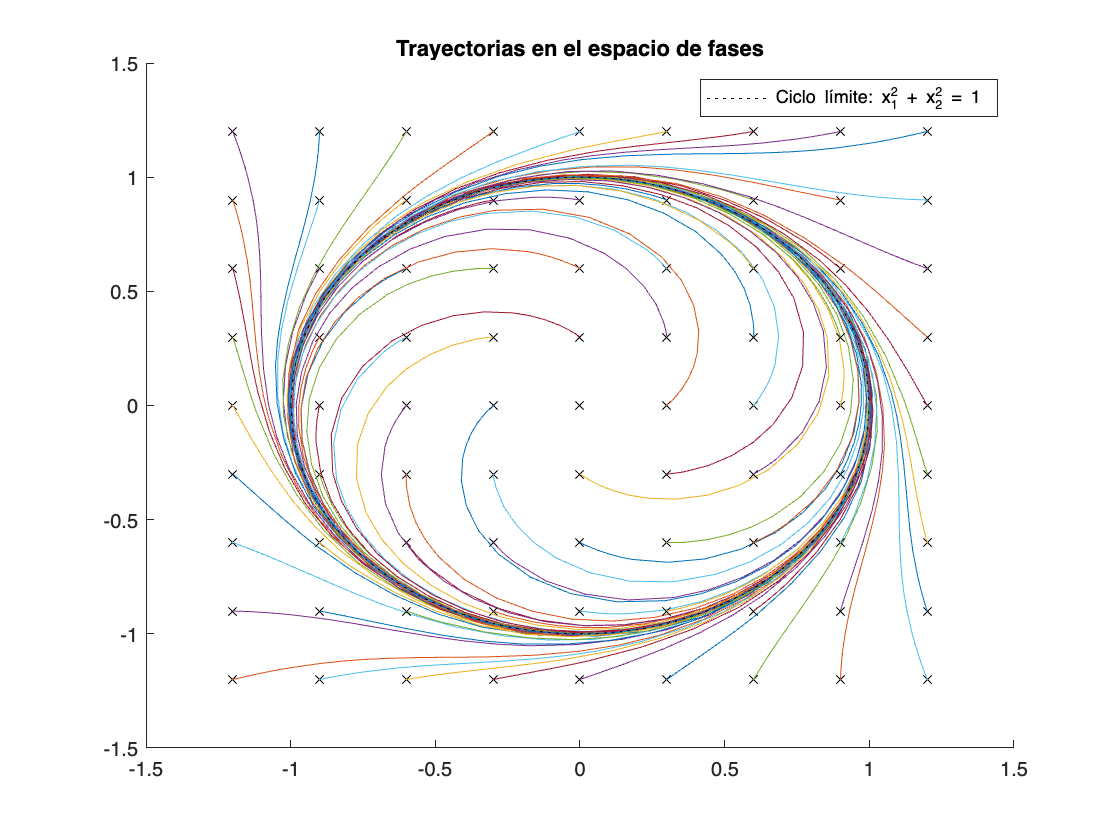

tspan = [0, -10];
x0 = [-1.2:0.3:1.2];
figure;
hold on;
for i = 1:length(x0)
    for j = 1:length(x0)
        [ti, xi] = ode45(@(t,x)sistema(t,x), tspan, [x0(i), x0(j)]');
        plot(x0(i), x0(j), "xk");
        plot(xi(:,1), xi(:,2));
    end
end

xc = [-1:0.01:1];
cp = plot(xc, (1-xc.^2).^.5, ":k"); %parte positiva de la circunferencia límite
cn = plot(xc, -(1-xc.^2).^.5, ":k"); %parte negativa
legend(cp, "Ciclo límite: x_1^2 + x_2^2 = 1")
title("Trayectorias en el espacio de fases")
xlim([-1.5, 1.5]);
ylim([-1.5, 1.5]);
hold off;

Integrando en tiempo negativo se observa el ciclo límite, luego se ve que hay un límite de estabilidad en la circunferencia de radio 1.  

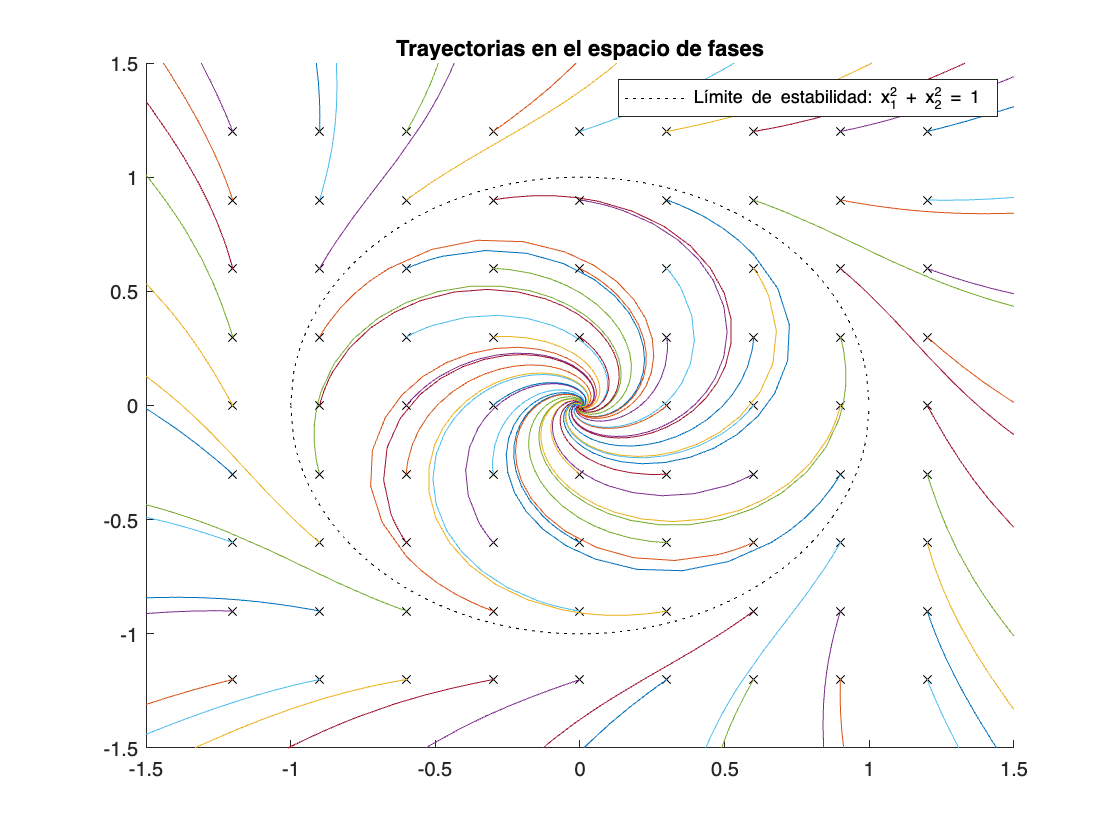

tspan = [0, 10];
x0 = [-1.2:0.3:1.2];
warning("off")
figure;
hold on;
for i = 1:length(x0)
    for j = 1:length(x0)
        [ti, xi] = ode45(@(t,x)sistema(t,x), tspan, [x0(i), x0(j)]');
        plot(x0(i), x0(j), "xk");
        plot(xi(:,1), xi(:,2));
    end
end

xc = [-1:0.01:1];
cp = plot(xc, (1-xc.^2).^.5, ":k"); 
cn = plot(xc, -(1-xc.^2).^.5, ":k"); 
legend(cp, "Límite de estabilidad: x_1^2 + x_2^2 = 1")
title("Trayectorias en el espacio de fases")
xlim([-1.5, 1.5]);
ylim([-1.5, 1.5]);
hold off;

Para radios mayores que 1 las trayectorias divergen. Para menores, convergen a (0 0).

**b)**

 El sistema a analizar es el del enunciado, con sus ecuaciones multiplicadas por -1. Aplicando las propiedades de las integrales, se puede deducir que integrar este sistema debería ser igual a integrar el primero en tiempo negativo, pero esto se puede comprobar. 

tspan = [0, 10];
x0 = [-1.2:0.3:1.2];
figure;
hold on;
for i = 1:length(x0)
    for j = 1:length(x0)
        [ti, xi] = ode45(@(t,x)sistemaejemplo(t,x), tspan, [x0(i), x0(j)]');
        plot(x0(i), x0(j), "xk");
        plot(xi(:,1), xi(:,2));
    end
end

xc = [-1:0.01:1];
cp = plot(xc, (1-xc.^2).^.5, ":k"); 
cn = plot(xc, -(1-xc.^2).^.5, ":k"); 
legend(cp, "Ciclo límite: x_1^2 + x_2^2 = 1")
title("Trayectorias en el espacio de fases")
xlim([-1.5, 1.5]);
ylim([-1.5, 1.5]);
hold off;

Que es el mismo resultado que se obtuvo al integrar en tiempo negativo el sistema del enunciado. 

function xdot = sistema(t, x)
    
    xdot(1,1) = -x(1,1) * (1 - x(1,1)^2 - x(2,1)^2) + x(2,1);
    xdot(2,1) = -x(2,1) * (1 - x(1,1)^2 - x(2,1)^2) - x(1,1);

end

function xdot = sistemaejemplo(t, x)
    xdot(1,1) = x(1,1) * (1 - x(1,1)^2 - x(2,1)^2) - x(2,1);
    xdot(2,1) = x(2,1) * (1 - x(1,1)^2 - x(2,1)^2) + x(1,1);
end